%根据Monte Carlo方法随机生成n个单元位置，
%计算邻接矩阵AM对应结构生成的化学概率
clc;
clear all;

n=4;
P1=[];
P2=[];

%AM为考察互锁结构的邻接矩阵
AM=ones(n);

for i=1:n
    AM(i,i)=0;
end

AM

AM =      0     1     1     1
     1     0     1     1
     1     1     0     1
     1     1     1     0



for l=4:0.1:5
L=(n-1)*l;

count1=0;
count2=0;

n_mer=0;
config=0;

%通过蒙特卡洛方法计算生成AM互锁结构的化学概率
for count=1:10^7
    density=[];
    a=-L;
    b=L;

    %R1为所有单体左端盖子位置的集合
    %R2为所有单体右端盖子位置的集合
    R1=[0];
    R2=[l];
    for s=2:n
        r=a+(b-a)*rand(1,1);
        R1=[R1 r];
        R2=[R2 r+l];
    end
        
    start=sort(R1);
        
    signal=1;
    
    %判断随机排列的n个单体是否生成n聚互锁结构(如是,signal=1)
    for i=2:size(start,2)
        if start(i)<=start(i-1)+l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end
    
    if signal==1

        Position=sort([R1 R2]);
        
        %根据各个盖子的位置计算相应n聚体的概率密度函数Ptotal
        for i=2:length(Position)
            density=[density,P(Position(i)-Position(i-1))];
        end
        
        density;
        Ptotal=prod(density);
        
        %计算所有n具体总的相体积(n_mer),以及满足AM互锁结构的相体积(config)
        n_mer=n_mer+Ptotal;
        count1=count1+1;
        if cat_config(AM,start,l)==1
            config=config+Ptotal;
            count2=count2+1;
        end
    end
end

count1;
n_mer;
count2;
config;
probability=config/n_mer
P1=[P1,probability];


%通过多重积分的方法求解出的闭锁概率
%计算通过逐步聚合方式沈城的四聚互锁结构1，2，3，4
%其中4为闭锁结构

%V1为结构1对应相体积
fun1 = @(x1,x2,x3) P(x1).*P(l-x1).*P(x2-l).*P(x1+l-x2)...
    .*P(x3-x1-l).*P(x2+l-x3).*P(x3-x2);
x3min= @(x1,x2) 1*x1+l;
x3max= @(x1,x2) 1*x2+l;
x2max= @(x1) 1*x1+l;
V1 = 1*integral3(fun1,0,l,l,x2max,x3min,x3max);

%V2为结构2对应相体积
fun2 = @(x1,x2,x3) P(x1).*P(l-x1).*P(x2-l).*P(x3-x2)...
    .*P(x1+l-x3).*P(x2-x1).*P(x3-x2);
x3min= @(x1,x2) 1*x2;
x3max= @(x1,x2) 1*x1+l;
x2max= @(x1) 1*x1+l;
V2 = 2*integral3(fun2,0,l,l,x2max,x3min,x3max);

%V3为结构3对应相体积
fun3 = @(x1,x2,x3) P(x1).*P(x2-x1).*P(l-x2).*P(x3-l)...
    .*P(x1+l-x3).*P(x2-x1).*P(x3-x2);
x3max= @(x1,x2) 1*x1+l;
x2min= @(x1) 1*x1;
V3 = 1*integral3(fun3,0,l,x2min,l,l,x3max);

%V4为结构4对应相体积
fun4 = @(x1,x2,x3) P(x1).*P(x2-x1).*P(x3-x2).*P(l-x3)...
    .*P(x1).*P(x2-x1).*P(x3-x2);
x3min= @(x1,x2) 1*x2;
x2min= @(x1) 1*x1;
V4 = 1*integral3(fun4,0,l,x2min,l,x3min,l);

interwoven_probability=V4/(V1+V2+V3+V4)

P2=[P2,interwoven_probability];
end

probability = 7.0040e-06

interwoven_probability = 5.3071e-06

probability = 0.0011

interwoven_probability = 0.0017

probability = 0.0584

interwoven_probability = 0.0584

probability = 0.4387

interwoven_probability = 0.3848

probability = 0.6375

interwoven_probability = 0.6648

probability = 0.7729

interwoven_probability = 0.7548

probability = 0.8001

interwoven_probability = 0.7783

probability = 0.7840

interwoven_probability = 0.7766

probability = 0.7683

interwoven_probability = 0.7637

probability = 0.7426

interwoven_probability = 0.7458

probability = 0.7241

interwoven_probability = 0.7264


X=4:0.1:5

X =     4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


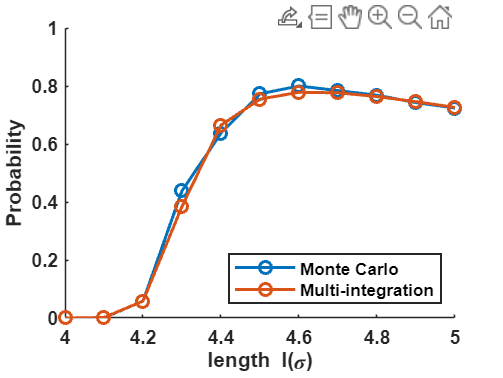

hold on
plot(X,P1,'-o',LineWidth=1.5)
plot(X,P2,'-o',LineWidth=1.5)
ylim([0 1]);

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('Probability','FontName','arial','FontWeight','bold');
legend( ['Monte Carlo'], ...
    ['Multi-integration'],...
    'Location','southeast','FontName','arial');

function BM=border(n)
%给定阶数n，生成对映的边界矩阵BM（border matrix）
%该矩阵对映了邻接矩阵AM上三角矩阵中处于0和1边界中1的位置
   BM=zeros(n);

if n==2
   BM(:,:,end+1)=[0 1;0 0];
end

if n>2
   A=border(n-1);
   C=zeros(1,n);
   for i=1:size(A,3)
        B=[zeros(n-1,1),A(:,:,i)];
        for j=2:find(B(1,:)==1)
            C(1,j)=1;
            BM(:,:,end+1)=[C;B];
            C=zeros(1,n);
        end
   end
end
BM(:,:,1)=[];
end
%-------------------------------------------------
function AM=adj_mat(n)
%根据边界矩阵BM，写出n阶所有邻接矩阵AM
BM=border(n);
AM=zeros(n);

for i=1:size(BM,3)
    A=BM(:,:,i);
    for j=1:n-1
        for k=j+1:find(A(j,:)==1)
            A(j,k)=1;
        end
    end
    A=A+A';
    AM(:,:,end+1)=A;
end
AM(:,:,1)=[];
end



%-------------------------------------------------
function signal=cat_config(AM,seq,l)
%根据邻接矩阵AM，判断随机给出单元位置坐标的数列是否属于该构型
ran=sort(seq);

signal=1;

for i=1:size(AM,1)
    pos1=find(AM(i,:)==1);
    pos2=find(AM(i,:)==0);
    pos2(pos2==i)=[];
    for j=1:length(pos1)
        if abs(ran(i)-ran(pos1(j)))<=l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end

    for j=1:length(pos2)
        if abs(ran(i)-ran(pos2(j)))>l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end
end

signal;
%signal=1则属于该构型，反之不属于
end


%-------------------------------------------------
function a= E(r) %定义特定的势能函数E(r)
    e=4120;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

%-------------------------------------------------
function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end






